# Initialization

clear all;

% accel data
accelerometer = load("X02299_ConflictTaskRun1.mat");

sampling = 1 / (accelerometer.isi / 1000);

% cued data
cued_data = load('02299_1_2022_Oct_06_1223_V_cued_r_time.mat');
cued_data.stimonset = round(cued_data.stimonset * 1000);
cued_data.presstime = round(cued_data.presstime * 1000);

# Filtering

% Isolating vibration at 75 nd 175 Hz
cutoff_low = 70; 
cutoff_high = 80; 
filter_order = 5;

[b, a] = butter(filter_order, [cutoff_low/(sampling/2), cutoff_high/(sampling/2)], 'bandpass');

vibration = filtfilt(b, a , accelerometer.data);

cutoff_low = 170; 
cutoff_high = 180; 
filter_order = 5;

[b, a] = butter(filter_order, [cutoff_low/(sampling/2), cutoff_high/(sampling/2)], 'bandpass');

insert = filtfilt(b, a , accelerometer.data);
vibration(insert > vibration) = insert(insert > vibration);

% Isolating movement
cutoff_low = 1; 
cutoff_high = 10; % around maximum of non trained human movement
filter_order = 3;

[b, a] = butter(filter_order, [cutoff_low/(sampling/2), cutoff_high/(sampling/2)], 'bandpass');

movement = filtfilt(b, a , accelerometer.data);

# 3.1 Segmenting

timewindows = [cued_data.stimonset(1:end-1);...
    cued_data.stimonset(2:end)];
timewindows = [timewindows [cued_data.stimonset(end); length(accelerometer.data(:,1))]];
timewindows

timewindows =        50566       61594       65394       68794       72594       76094       79494       82894       86194       89894       92894       96594       99794      103094      106894      110294      114094      117594      120594      124494      128394      132093      142127      145494      149194      152594      156494      160094      163994      167694      170794      174694      178594      182094      185294      188394      191894      195094      198894      201994      205794      209094      212893      222915      226794      229794      232894      236194      239394      242894
       61594       65394       68794       72594       76094       79494       82894       86194       89894       92894       96594       99794      103094      106894      110294      114094      117594      120594      124494      128394      132093      142127      145494      149194      152594      156494      160094      163994      167694      170794      174694      178594 

# Plotting

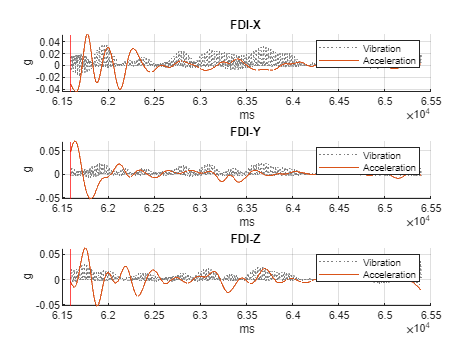

figure()

for i = 1:length(accelerometer.data(1,:))/2
    subplot(3,1,i)
    
    window = movement(timewindows(1,2):timewindows(2,2), i);
    vibration_window = vibration(timewindows(1,2):timewindows(2,2), i);
    t = linspace(timewindows(1,2),timewindows(2,2),length(window));
    
    hold on
    plot(t, vibration_window, 'LineStyle',':', 'Color', [0.5 0.5 0.5])
    plot(t, window)
    xline(cued_data.stimonset(2), 'r')
    hold off

    title(accelerometer.labels(i,1:6))
    ylabel(accelerometer.units(i))
    xlabel(accelerometer.isi_units)
    grid("on")
    legend("Vibration", "Acceleration")
end

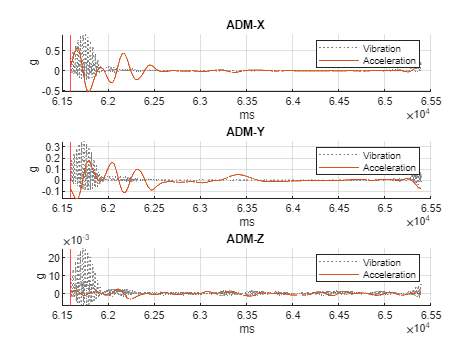


figure()
for i = 4:length(accelerometer.data(1,:))
    subplot(3,1,i-3)
    
    window = movement(timewindows(1,2):timewindows(2,2), i);
    vibration_window = vibration(timewindows(1,2):timewindows(2,2), i);
    t = linspace(timewindows(1,2),timewindows(2,2),length(window));

    hold on
    plot(t, vibration_window, 'LineStyle',':', 'Color', [0.5 0.5 0.5])
    plot(t, window)
    xline(cued_data.stimonset(2), 'r')
    hold off
    
    title(accelerometer.labels(i,1:6))
    ylabel(accelerometer.units(i))
    xlabel(accelerometer.isi_units)
    grid("on")
    legend("Vibration", "Acceleration")
end